## Pregunta 1. 

Qué número real x está representado en punto flotante de doble precisión por la siguiente cadena hexadecimal? 

hex = '3fe921fb54442d18'; % estándar IEEE 754
bin = '0011111111101001001000011111101101010100010001000010110100011000';

Extrae los diferentes campos del número binario bin 

s = bin(1) % Sign

s = '0'

e = bin([2:12]) % Exponent

e = '01111111110'


f = bin([13:64]) % Mantissa bits

f = '1001001000011111101101010100010001000010110100011000'

Calcula el signo s (-1 o 1) 

s = bin2dec(s);
s = -1^s

s = -1

Calcula el exponente con bias be 

be = bin2dec(e)

be = 1022

Calcula el exponente e 

e = be - 1023

e = -1

Calcula la mantisa 

f = bin2dec(f)/2^52

f = 0.5708

Calcula el número real x 

x = (1+f)*2^e

x = 0.7854

## Pregunta 2. 

Observa el resultado de la siguiente expresión. 

res = (7/100)*100 - 7

res = 8.8818e-16

¿Por qué res no es igual a 0? 

% Errores de redondeo en la división 7/10, por lo que redondea generando
% un error

Encuentra n tal que res = eps(n) y verifica tu respuesta usando la función de MATLAB isequal 

n = 1:1:10

n =      1     2     3     4     5     6     7     8     9    10


X = eps(n)

X = 1.0e-14 *

    0.0222    0.0444    0.0444    0.0888    0.0888    0.0888    0.0888    0.1776    0.1776    0.1776


a = X(X == res)

a = 1.0e-15 *

    0.8882    0.8882    0.8882    0.8882


isequal(res,a(1))

ans = logical
   1


isequal(res,a(2))

ans = logical
   1


isequal(res,a(3))

ans = logical
   1


isequal(res,a(4))

ans = logical
   1


% Se cumple que res = eps(n) para n = 4,5,6,7

## Pregunta 3. 

Calcula el error de la aproximación de la primera derivada centrada de cinco puntos de la función $f\left(x\right)=\sin \left(x^2 \right)$en el punto $x=2\;$como función del espaciado h entre los valores de x. 

Calcula el valor exacto dftrue de la derivada de la función en el punto .

f = @(x) sin(x.^2);
fd = matlabFunction(diff(sym(f))); % = @(x) 2*x.*cos(x.^2)
x = 2;
dftrue = fd(x)

dftrue = -2.6146

Calcula el valor absoluto te del error para . h...

[h, dfs, err] = firstDerCOrd4(f,2)

h =     1.0000    0.1000    0.0100    0.0010    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000


dfs =    -0.2622   -2.6097   -2.6146   -2.6146   -2.6146   -2.6146   -2.6146   -2.6146   -2.6146   -2.6146


err =     2.3523    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


verr = abs(err)

verr =     2.3523    0.0048    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


Gráfica el valor absoluto del error te vs. h en una escala logarítmica (loglog) 

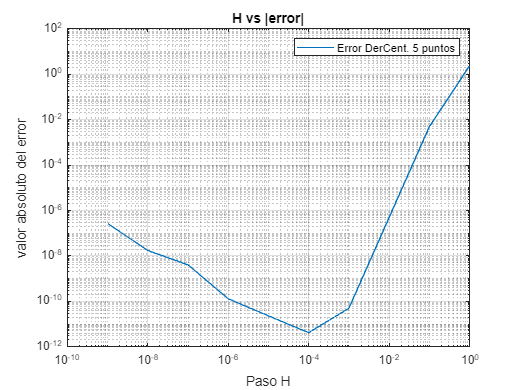

loglog(h,verr)
grid on
title('H vs |error|')
xlabel('Paso H')
ylabel('valor absoluto del error')
legend('Error DerCent. 5 puntos')
hold off

Calcula el valor de h que debe usarse para tener la mejor exactitud. 

% Encontrando el error mínimo de aproximación así como el índice en el
% que se encuentra
[Hmin,idx] = min(verr)

Hmin = 4.1762e-12

idx = 5

% El valor de H óptimo es
hOpt = h(idx)

hOpt = 1.0000e-04

Dado que el error de truncamiento de la aproximación es [...FORMULA...], donde [LETRA GRIEGA] es un punto en el dominio, el error debería disminuir siempre que se reduzca h. Explica entonces ¿por qué aumenta el error al reducir h a partir del mínimo encontrado? 

% Debido a que matlab no puede representar con precisión los número
% cuando se empiezan a hacer muy pequeños, entonces la pequeña variación
% con respecto al valor real aumenta conforme H se hace aún más pequeña.

## Pregunta 4. 

Resuelve la ecuación x=cos(x). 

La ecuación puede reformularse para encontrar las raíces de una función (anónima) f1.

f1 = @(x) x - cos(x);

Grafica la función f1 en el intervalo [-2,2] 

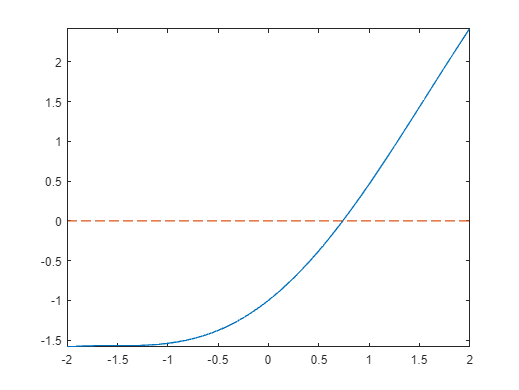

fplot(f1)
xlim([-2 2])
hold on
y = 0;
fplot(y,'--')
hold off

¿Cuántas raíces (ceros) tiene f1? 

Encuentra una raíz de f1 usando la función de MATLAB fzero y el valor inicial x=0.5. 

x = fzero(f1,0.5)

x = 0.7391

Encuentra una raíz de f1 usando la función de MATLAB fzero y el valor inicial x=1.  

x = fzero(f1,1)

x = 0.7391

Resuelve la ecuación x=sin(x). 

Reformula la ecuación para encontrar las raíces de una función f2 

f2 = @(x) x - sin(x)

f2 = function_handle with value:
    @(x)x-sin(x)


Grafica la función f2 en el intervalo [-2,2] 

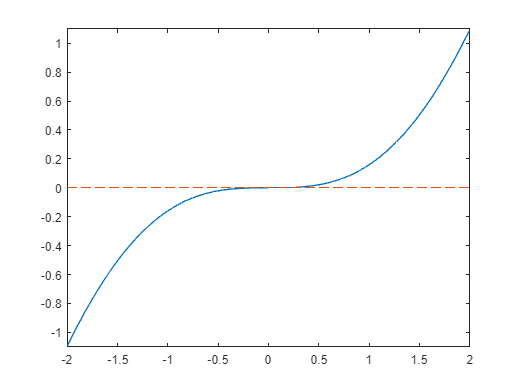

fplot(f2)
xlim([-2 2])
hold on
y = 0;
fplot(y,'--')
hold off

¿Cuántas raíces (ceros) tiene f2? 

Encuentra una raíz de f2 usando la función de MATLAB fzero y el valor inicial x=-0.5. 

x = fzero(f2,-0.5)

x = 4.6469e-09

Encuentra una raíz de f2 usando la función de MATLAB fzero y el valor inicial x=0.  

x = fzero(f2,0)

x = 0

Encuentra una raíz de f2 usando la función de MATLAB fzero y el valor inicial x=0.5.  

x = fzero(f2,0.5)

x = -4.6469e-09

¿Cuántas raíces (ceros) tiene f2? 

¿En qué puntos sin(x)/x = 1 ? Explica qué observas 

% f2 tiene 3 raices según el método fzero de matlab

% Realizando la aproximación con otros métodos
O1_proporcionAurea(f2,-0.3,0.3)

ans = -0.3000

O2_newtonRaphsonMinimo(f2,0.01)

ans = 1.3860e-09

% Se observa que los métodos programados también fallan al
% aproximar la raíz de f2

% Calculando sin(x)/x -1 = 0
f3 = @(x) sin(x)./x - 1

f3 = function_handle with value:
    @(x)sin(x)./x-1


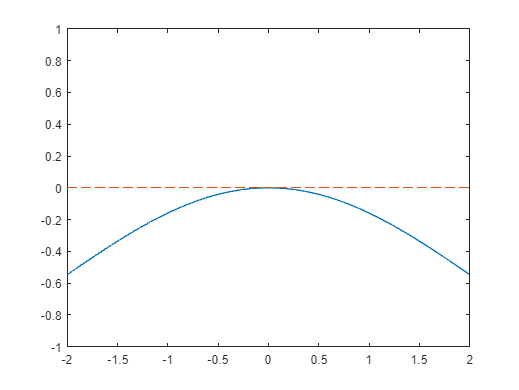

fplot(f3)
xlim([-2 2])
ylim([-1 1])
hold on
y = 0;
fplot(y,'--')
hold off


% Aproximando con búsqueda dorada
g = @(x) -f(x)

g = function_handle with value:
    @(x)-f(x)


O1_proporcionAurea(g,-0.5,0.5)

ans = -0.5000


%Aproximando con optimización de Newton
O2_newtonRaphsonMinimo(f3,0.01)

ans = Inf


%Aproximando con IPS
O3_IPS(f3,-0.1, 0, 0.1)

ans = NaN


% Gráficamente se observa que f3 (y por tanto f2) tiene una raíz en
% x = 0. Sin embargo, como la función incluye una división entre x,
% entonces el 0 no puede estar en el dominio de la f. Así mismo,
% los métodos fallan al intentar aproximar dicha raíz.

## Pregunta 5. 

Resuelve la ecuación $x^4 =2$. 

Reformula la ecuación para encontrar las raíces de una función f.

f = @(x) x.^4 - 2

f = function_handle with value:
    @(x)x.^4-2


Grafica la función entre -1.5 y 1.5. 

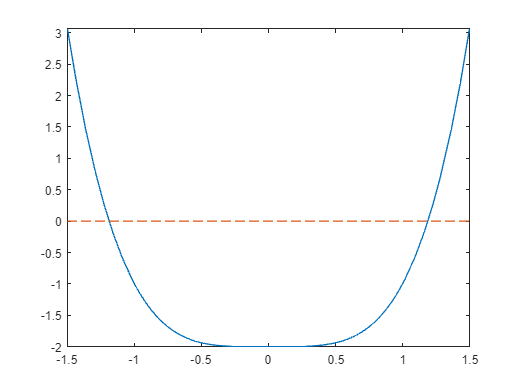

fplot(f)
xlim([-1.5 1.5])
hold on
y = 0;
fplot(y,'--')
hold off

Encuentra la raíz real positiva usando el método de Newton-Raphson y la aproximación inicial Xo = 1.

x = R4_rfNewton(f,1)

x = 1.1892

¿Para qué valor real el método no converge? 

% Si x = 0 entonces el método de Newton Raphson no converge
R4_rfNewton(f,0)

ans = Inf

%Esto es debido a que el método de NR busca cambios de signos a través de
%distintos intervalos. Notamos que si estamos exactamente en x=0 no detecta
%ningún cambio de comportamiento en sus laterales.

## Pregunta 6. 

Encuentra en qué valor de x ocurre el máximo de la función $f\left(x\right)=2\sin \left(x\right)-\frac{x^2 }{10}$ y cuál es el valor máximo, usando alguno de los métodos vistos en clase.

% Definiendo la función
f = @(x) 2 * sin(x) - (x.^2)/10

f = function_handle with value:
    @(x)2*sin(x)-(x.^2)/10



% Graficando
fplot(f)
xlim([0 4])
ylim([-3 3])
hold on

% Optimizando con Newton
x = O2_newtonRaphsonMinimo(f,0.5)

x = 1.4276

Verifica tu solución usando la función de MATLAB fminbnd. 

g = @(x) - f(x)

g = function_handle with value:
    @(x)-f(x)


x = fminbnd(g,0.5,2)

x = 1.4275

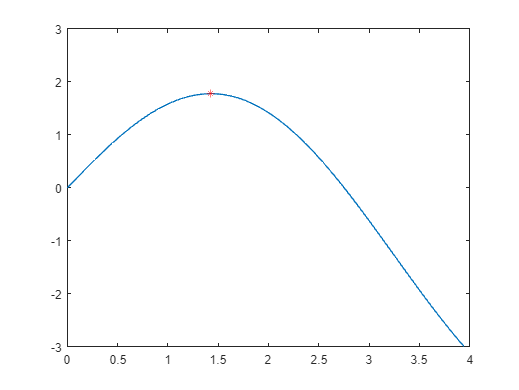

plot(x,f(x),'*r')
hold off

Encuentra la derivada df de la función  

% Declarando la derivada
df = matlabFunction(diff(sym(f)))

df = function_handle with value:
    @(x)x.*(-1.0./5.0)+cos(x).*2.0


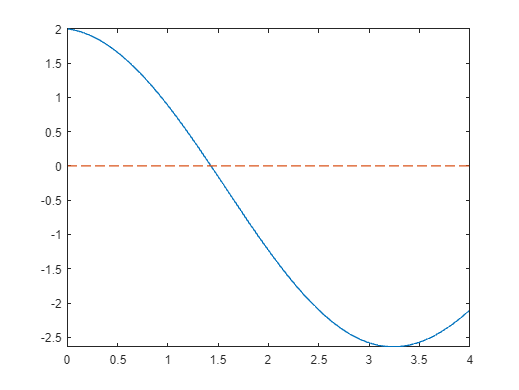


% Graficando
fplot(df)
xlim([0 4])
hold on
y = 0;
fplot(y,'--')

Encuentra en dónde vale cero df usando todos los algoritmos

[x1(1),i1(1)] = R1_Biseccion(df,1,2);
[x1(2),i1(2)] = R2_Interpolacion(df,1,2);
[x1(3),i1(3)] = R3_Secante(df,1,2);
[x1(4),i1(4)] = R4_rfNewton(df,1.5);
[x1(5),i1(5)] = R5_InterpolacionCuadraticaInversa(df, 1,1.5,2);
x1

x1 =     1.4276    1.4276    1.4276    1.4276    1.4247


% Que es el mismo punto que el calculado con los métodos

## Pregunta 7. 

Encuentra una fórmula para encontrar la siguiente aproximación en el método de interpolación parabólica sucesiva que calcula un punto crítico de una función f. Puedes usar el polinomio de interpolación de Lagrange (para obtener la fórmula del libro de texto) o el de Newton (para obtener la fórmula de la presentación del curso). Inserta aquí una foto del procedimiento.

## Pregunta 8.

Código Newton-Rhapson.

## Pregunta 9.

Código de algún método de optimización (consejo, no poner el de newton porque tiene derivadas simbólicas).

## Pregunta 10.

Algún código de raices, probablemente la interpolación cuadrática inversa.